#### **Naprendszer szimuláció**

A Newton-féle gravitációs törvényből levezethető a mozgásegyenlete a Földnek:

$$$F=-G \frac{mM}{r^2}\cdot \hat{r}$$$, ahol m a Föld tömege, M a Nap tömege, G a gravitációs állandó, r a Nap és a Föld távolsága. Mivel $$F=ma=m\ddot{r}$$, így $$$\ddot{r}=-G\frac{M}{r^2}\cdot \hat{r}$$$.

x és y irányú összetevőkre bontva:

$$$a_x=-G\frac{M}{r^3}x$$$, és $$$a_y=-G\frac{M}{r^3}y$$$.

A potenciális, illetve a kinetikus energiát a következő képletekkel számítottam:

$$$E_{kin}=\frac{1}{2}mv^2=\frac{1}{2}m(v_x^2+v_y^2)$$$, $$E_{pot}=-G\frac{mM}{r}$$.

A konstansoknak és állandóknak a következő értékeket adtam:

clear all, close all;
M=1.98847e+30;      %Nap tömege [kg]
m=5.9722e+24;       %Föld tömege [kg]
G=6.67404e-11;      %gravitációs állandó [m^3*kg^{-1}*s^{-2}]
r_nap=696342000;    %Nap sugara [m]

R=149.6e+9;     %átlagos távolság a Naptól [m]

A Föld keringési idejének az átlagát vettem másodpercben kifejezve, illetve a lépésköznek 1 napot választottam, szintén másodpercben. A szimuláció kezdeti ponjának az $$(x_0, y_0)=(R, 0)$$ pontot választottam, ahol a kezdeti sebesség megegyezik az y irányú gyorsulással, $$v_0=\sqrt{v_x^2+v_y^2}$$, mivel $$v_{x0}=0$$, ezért $v_{y0}=v_0$. A szimulációban négyszer ér körbe a Föld a Nap körül:

year=4;

T=365.256*24*60*60*year;     %keringési idő [s]
dt=24*60*60;        %lépésköz; 1 nap [s]

x=R;
y=0;
v0=29.78e+3;
vx=0;
vy=v0;
t=0;        %kezdettől eltelt idő;
E_pot=-G*M*m / (x^2+y^2);
E_kin=(vx^2+vy^2)*m / 2;
E_sum=E_pot+E_kin;


Először **Euler módszer**rel számítottam a Föld pályáját a Nap körül. Ehhez a következő egyenleteket használtam fel:

$a_x=-G\frac{M}{(x^2+y^2)^\frac{3}{2}}\cdot x$, és $a_y=-G\frac{M}{(x^2+y^2)^\frac{3}{2}}\cdot y$

$v_x=v_x+a_x\cdot dt$, és $v_y=v_y+a_y\cdot dt$

$x=x+v_x\cdot dt
$, és $y=y+v_y\cdot dt$

ahol a lépésköz: $dt=24\cdot60\cdot60$, ami 1 napnak felel meg másodpercben.

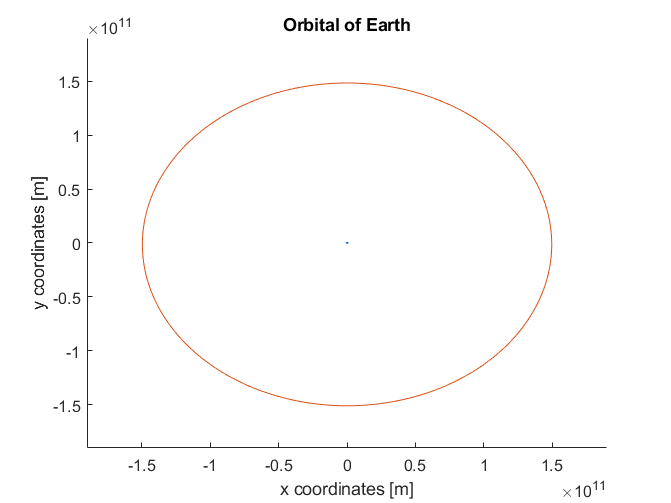


x_=[x];
y_=[y];
vx_=[vx];
vy_=[vy];
E_pot_=[E_pot];
E_kin_=[E_kin];
E_sum_=[E_sum];
t_=[t];

figure(1);

th=0:pi/60:2*pi;
xunit=r_nap*cos(th);
yunit=r_nap*sin(th);
hold on;
plot(xunit, yunit)

for i = 0:(T/dt)
    
        R=sqrt(x^2+y^2);
        
        ax=-G*M*x /R^3;
        ay=-G*M*y /R^3;

        vx=vx+ax*dt;
        vy=vy+ay*dt;

        vx_=[vx_ vx];
        vy_=[vy_ vy];

        x=x+vx*dt;
        y=y+vy*dt;

        x_=[x_ x];
        y_=[y_ y];
        
        t=t+dt;
        t_=[t_ t];
        
        E_pot=-G*M*m / (x^2+y^2);
        E_kin=(vx^2+vy^2)*m / 2;
        E_sum=E_pot+E_kin;
        
        E_pot_=[E_pot_ E_pot];
        E_kin_=[E_kin_ E_kin];
        E_sum_=[E_sum_ E_sum];
end
    plot(x_, y_)
    xlim([-190e+9, 190e+9]);
    ylim([-190e+9, 190e+9]);
    xlabel('x coordinates [m]');
    ylabel('y coordinates [m]');
    title('Orbital of Earth');

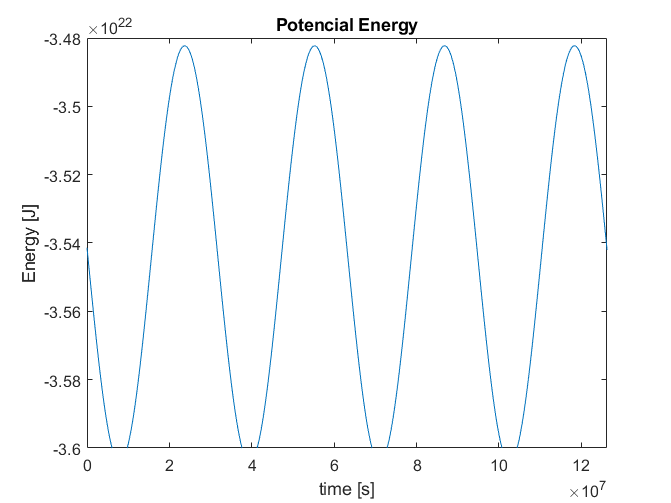

    
    figure(2);
    plot(t_, E_pot_)
    xlim([0, 365.256*24*60*60*year]);
    ylim([-3.60e+22, -3.48e+22]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Potencial Energy');

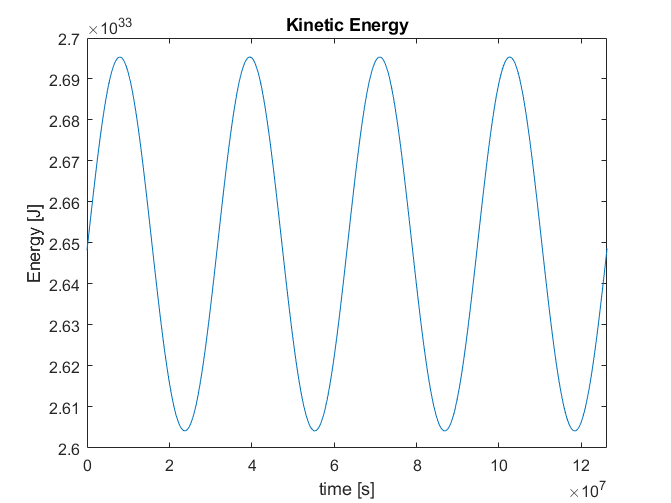

    
    figure(3);
    plot(t_, E_kin_)
    xlim([0, 365.256*24*60*60*year]);    
    ylim([2.6e+33, 2.7e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Kinetic Energy');

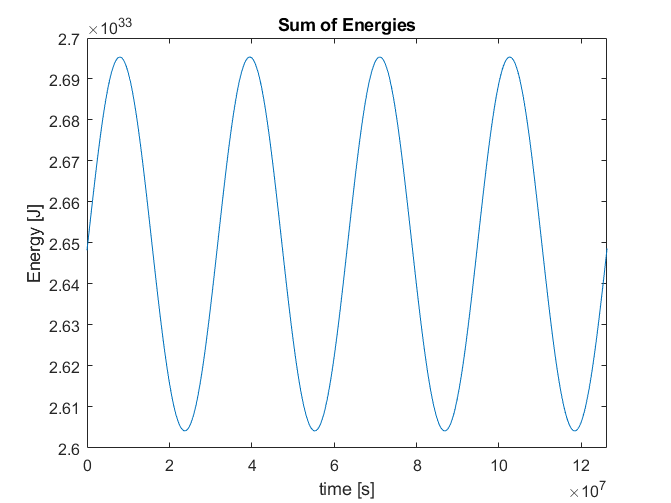

    
    figure(4);
    plot(t_, E_sum_)
    xlim([0, 365.256*24*60*60*year]);    
    ylim([2.6e+33, 2.7e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Sum of Energies');

Ezután a Föld pályáját a mozgásegyenlet alapján a **Runge Kutta 4th** numerikus módszerrel számítottam ki. A megoldás és az egyenletrendszer a for ciklusban található, $dt=24\cdot60\cdot 60$ [s] lépésközzel számolva. Ebben a kódrészletben is 4 évre számítottam a Föld pályáját, azaz 4-szer kering körül a Nap körül. A módszer hatékonysága: a becsült és kapott érték és a valódi függvény érték közötti hibára adott felső becslés a választott lépésköz 4. hatványával arányosan csökken.

Az Euler módszerrel összehasonlítva sokkal kisebb a hibaarány, és pontosabb a számítás. Ez a potenciális és kinetikus energia összegének változásával szemléltethető jól. Az energiamegmaradás törvény és a Hamilton elv következménye, hogy az összenergiának állandó, konstans értéknek kell lennie. A Runge Kutta 4th módszernél sokkal kisebb az összenergia időbeni változása, mint az Euler módszerben számított összenergia időbeni változása.

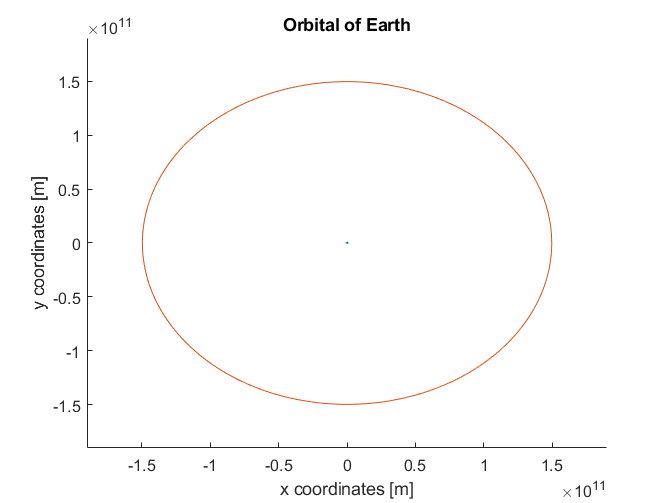

M=1.98847e+30;      %Nap tömege [kg]
m=5.9722e+24;       %Föld tömege [kg]
G=6.67404e-11;      %gravitációs állandó [m^3*kg^{-1}*s^{-2}]
r_nap=696342000;

R=149.6e+9;     %átlagos távolság a Naptól [m]

year=4;

T=365.256*24*60*60*year;     %keringési idő*évek [s]
dt=24*60*60;        %lépésköz; 1 nap [s]

x=R;
y=0;
v0=29.78e+3;
vx=0;
vy=v0;
t=0;        %kezdettől eltelt idő;
E_pot=-G*M*m / (x^2+y^2);
E_kin=(vx^2+vy^2)*m / 2;
E_sum=E_pot+E_kin;

x_=[x];
y_=[y];
vx_=[vx];
vy_=[vy];
E_pot_=[E_pot];
E_kin_=[E_kin];
E_sum_=[E_sum];
t_=[t];

figure(5);

th=0:pi/60:2*pi;
xunit=r_nap*cos(th);
yunit=r_nap*sin(th);
hold on;
plot(xunit, yunit)

for i = 0:(T/dt)
        ax=-G*M*x /R^3;
        ay=-G*M*y /R^3;
        
        R=sqrt(x^2+y^2);

        v_x(1)=-dt*G*M*x / R^3;
        v_y(1)=-dt*G*M*y / R^3;
        x_k(1)=dt*vx;
        y_k(1)=dt*vy;
        
        v_x(2)=-dt*G*M*(x+x_k(1)/2) / R^3;
        v_y(2)=-dt*G*M*(y+y_k(1)/2) / R^3;
        x_k(2)=dt*(vx+v_x(1)/2);
        y_k(2)=dt*(vy+v_y(1)/2);
        
        v_x(3)=-dt*G*M*(x+x_k(2)/2) / R^3;
        v_y(3)=-dt*G*M*(y+y_k(2)/2) / R^3;
        x_k(3)=dt*(vx+v_x(2)/2);
        y_k(3)=dt*(vy+v_y(2)/2);
        
        v_x(4)=-dt*G*M*(x+x_k(3)) / R^3;
        v_y(4)=-dt*G*M*(y+y_k(3)) / R^3;
        x_k(4)=dt*(vx+v_x(3));
        y_k(4)=dt*(vy+v_y(3));
        
        vx=vx+(v_x(1)+2*v_x(2)+2*v_x(3)+v_x(4))/6;
        vy=vy+(v_y(1)+2*v_y(2)+2*v_y(3)+v_y(4))/6;
        
        vx_=[vx_ vx];
        vy_=[vy_ vy];
        
        x=x+(x_k(1)+2*x_k(2)+2*x_k(3)+x_k(4))/6;
        y=y+(y_k(1)+2*y_k(2)+2*y_k(3)+y_k(4))/6;
        
        x_=[x_ x];
        y_=[y_ y];
        
        t=t+dt;
        t_=[t_ t];
        
        E_pot=-G*M*m / (x^2+y^2);
        E_kin=(vx^2+vy^2)*m / 2;
        E_sum=E_pot+E_kin;
        
        E_pot_=[E_pot_ E_pot];
        E_kin_=[E_kin_ E_kin];
        E_sum_=[E_sum_ E_sum];
end
    plot(x_, y_)
    xlim([-190e+9, 190e+9]);
    ylim([-190e+9, 190e+9]);
    xlabel('x coordinates [m]');
    ylabel('y coordinates [m]');
    title('Orbital of Earth');

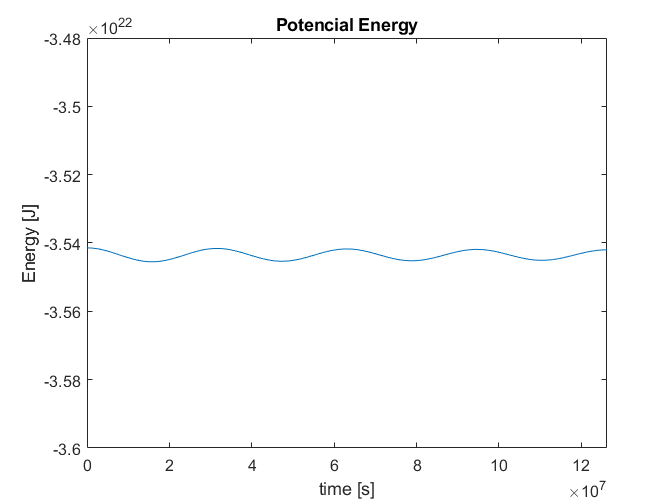

    
    figure(6);
    plot(t_, E_pot_)
    xlim([0, 365.256*24*60*60*year]);
    ylim([-3.60e+22, -3.48e+22]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Potencial Energy');

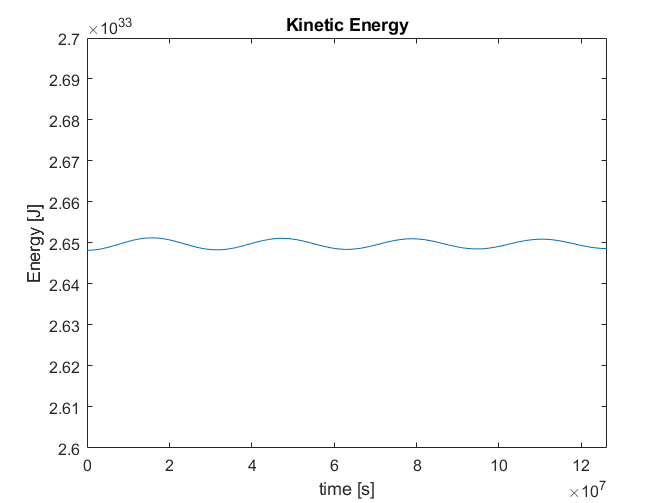

    
    figure(7);
    plot(t_, E_kin_)
    xlim([0, 365.256*24*60*60*year]);    
    ylim([2.6e+33, 2.7e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Kinetic Energy');

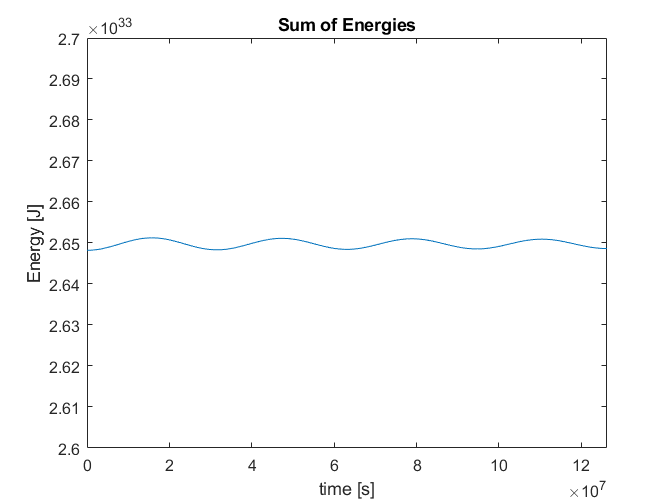

    
    figure(8);
    plot(t_, E_sum_)
    xlim([0, 365.256*24*60*60*year]);    
    ylim([2.6e+33, 2.7e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Sum of Energies');

A következő kódrészletben egy **üstökös pályá**ját modellezem a Runge Kutta 4th numerikus módszerrel. A Halley üstököst vettem modellül, keringési ideje itt$T=\frac{2.4819 \cdot 10^9}{60\cdot60\cdot24\cdot365.256}=78.6454$ év. Az előbbi számításhoz képest a különbségek: sokkal messzebbről "indítjuk" az üstököst, és Naptávolban sokkal kisebb a sebessége, mint a Földnek, és sokkal kisebb a tömege is, illetve a lépésköz a sugár függvényében változik. Itt is a kiindulópont: $(x_0, y_0)=(R, 0)$ és $v_{y0}=v_0, v_{x0}=0$. A potenciális és kinetikus energiát hasonlóan számoljuk, mint az előbbiekben. Látható, hogy napközelben megnő a kinetikus energiája a nagyobb sebesség miatt.

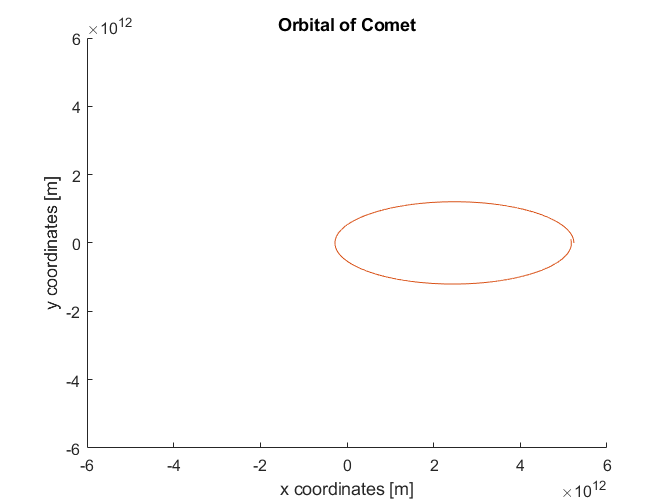

M=1.98847e+30;      %Nap tömege [kg]
m=2.2e+14;       %üstökös tömege [kg]
G=6.67404e-11;      %gravitációs állandó [m^3*kg^{-1}*s^{-2}]
r_nap=696342000;

R=5.2359e+12;     %legnagyobb távolság a Naptól [m]

T=365.256*24*60*60*152;

dt=24*60*60;        %lépésköz; 1 nap [s]

x=R;
y=0;
v0=1.6e+3;
vx=0;
vy=v0;
t=0;        %keztettől eltelt idő;
E_pot=-G*M*m / (x^2+y^2);
E_kin=(vx^2+vy^2)*m / 2;
E_sum=E_pot+E_kin;

x_=[x];
y_=[y];
vx_=[vx];
vy_=[vy];
E_pot_=[E_pot];
E_kin_=[E_kin];
E_sum_=[E_sum];
t_=[t];

figure(9);

th=0:pi/60:2*pi;
xunit=r_nap*cos(th);
yunit=r_nap*sin(th);
hold on;
plot(xunit, yunit)

for i = 0:(T/dt)
        ax=-G*M*x /R^3;
        ay=-G*M*y /R^3;
        
        R=sqrt(x^2+y^2);
        dt=24*60*60*R/(5.2359e+12);
        
        v_x(1)=-dt*G*M*x / R^3;
        v_y(1)=-dt*G*M*y / R^3;
        x_k(1)=dt*vx;
        y_k(1)=dt*vy;
        
        v_x(2)=-dt*G*M*(x+x_k(1)/2) / R^3;
        v_y(2)=-dt*G*M*(y+y_k(1)/2) / R^3;
        x_k(2)=dt*(vx+v_x(1)/2);
        y_k(2)=dt*(vy+v_y(1)/2);
        
        v_x(3)=-dt*G*M*(x+x_k(2)/2) / R^3;
        v_y(3)=-dt*G*M*(y+y_k(2)/2) / R^3;
        x_k(3)=dt*(vx+v_x(2)/2);
        y_k(3)=dt*(vy+v_y(2)/2);
        
        v_x(4)=-dt*G*M*(x+x_k(3)) / R^3;
        v_y(4)=-dt*G*M*(y+y_k(3)) / R^3;
        x_k(4)=dt*(vx+v_x(3));
        y_k(4)=dt*(vy+v_y(3));
        
        vx=vx+(v_x(1)+2*v_x(2)+2*v_x(3)+v_x(4))/6;
        vy=vy+(v_y(1)+2*v_y(2)+2*v_y(3)+v_y(4))/6;
        
        vx_=[vx_ vx];
        vy_=[vy_ vy];
        
        x=x+(x_k(1)+2*x_k(2)+2*x_k(3)+x_k(4))/6;
        y=y+(y_k(1)+2*y_k(2)+2*y_k(3)+y_k(4))/6;
        
        x_=[x_ x];
        y_=[y_ y];
        
        t=t+dt;
        t_=[t_ t];
        
        E_pot=-G*M*m / (x^2+y^2);
        E_kin=(vx^2+vy^2)*m / 2;
        E_sum=E_pot+E_kin;
        
        E_pot_=[E_pot_ E_pot];
        E_kin_=[E_kin_ E_kin];
        E_sum_=[E_sum_ E_sum];
end
    plot(x_, y_)
    xlim([-6e+12, 6e+12]);
    ylim([-6e+12, 6e+12]);
    xlabel('x coordinates [m]');
    ylabel('y coordinates [m]');
    title('Orbital of Comet');

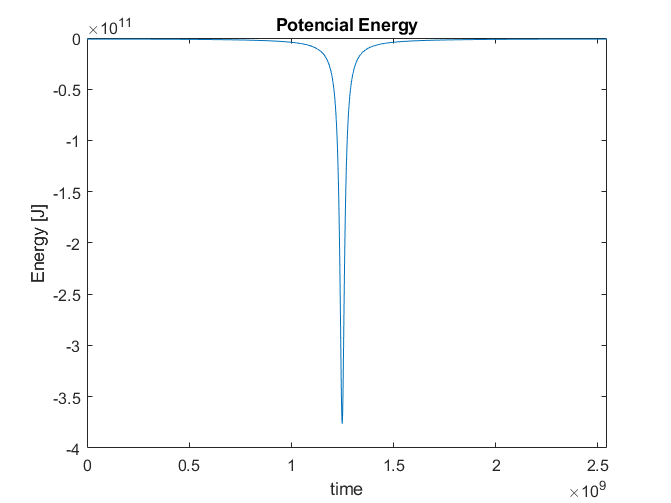

    
    figure(10);
    plot(t_, E_pot_)
    xlim([0, t]);
 %   ylim([-3.60e+22, -3.48e+22]);
    xlabel('time');
    ylabel('Energy [J]');
    title('Potencial Energy');

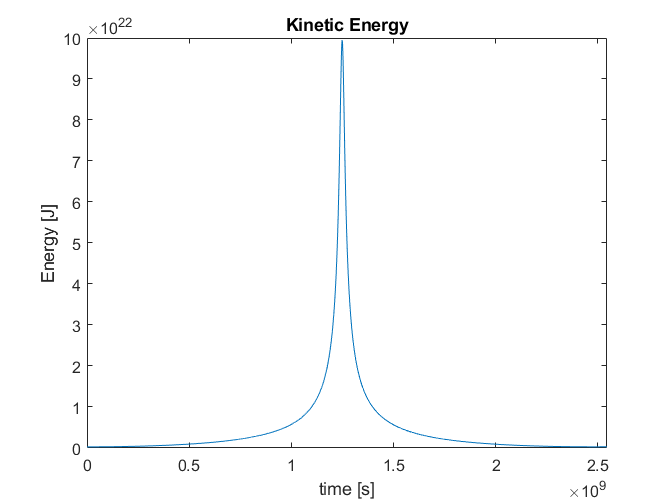

    
    figure(11);
    plot(t_, E_kin_)
    xlim([0, t]);    
  %  ylim([2.6e+33, 2.7e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Kinetic Energy');

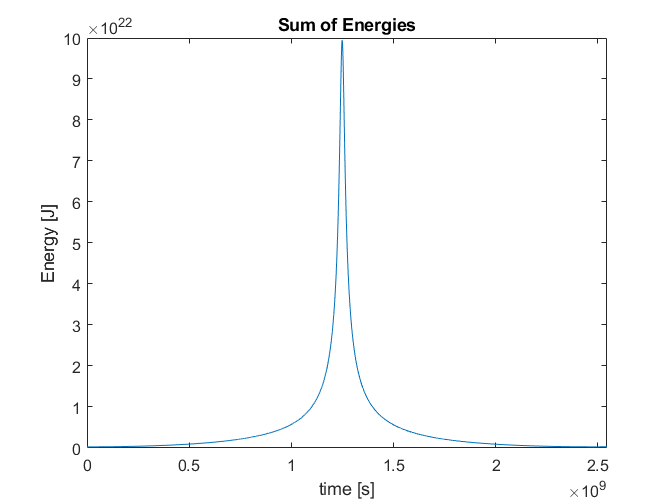

    
    figure(12);
    plot(t_, E_sum_)
    xlim([0, t]);    
  %  ylim([2.6e+33, 2.7e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Sum of Energies');

A következő megvalósítást az **ode45** beépített differenciálegyenlet megoldó funkcióval készítettem, Deascartes koordinátarendszerben. Az ehhez szükséges egyenlet és elsőrendű egyenletrendszer:

$a_x=-G\frac{M}{(x^2+y^2)^\frac{3}{2}}\cdot x$, és $a_y=-G\frac{M}{(x^2+y^2)^\frac{3}{2}}\cdot y$

$u(1)=\dot{x}$, $u(2)=\dot{y}$, $$u(3)=x$, $u(4)=y$.

Látható, hogy nem kapunk pontos eredményt.

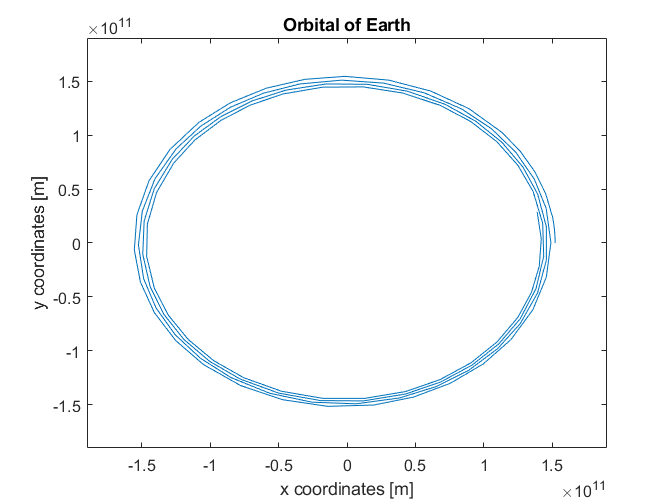

M=1.98847e+30;      %Nap tömege [kg]
m=5.9722e+24;       %Föld tömege [kg]
G=6.67404e-11;      %gravitációs állandó [m^3*kg^{-1}*s^{-2}]
r_nap=696342000;

R=152.10e+9;     %átlagos távolság a Naptól [m]

year=4;

T=365.256*24*60*60*year;     %keringési idõ [s]

figure(13);
keztedi_feltetelek=[0, 29780, R, 0];

diff= @(t, u) [-G*M*u(3)/(u(3)^2+u(4)^2)^(3/2); -G*M*u(4)/(u(3)^2+u(4)^2)^(3/2); u(1); u(2)];
[U, V]=ode45(diff, [0, T], keztedi_feltetelek);

plot(V(:,3), V(:,4));
xlim([-190e+9, 190e+9]);
ylim([-190e+9, 190e+9]);
xlabel('x coordinates [m]');
ylabel('y coordinates [m]');
title('Orbital of Earth');

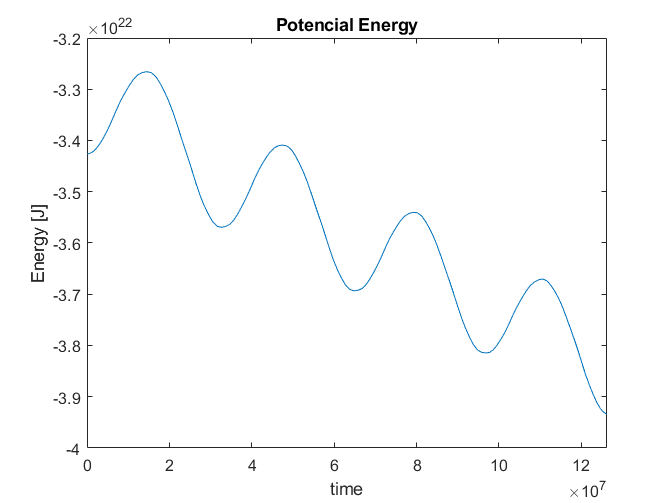


    figure(14);
    plot(U(:,1), -G*M*m./(V(:,3).^2+V(:,4).^2))
    xlim([0, T]);
  %  ylim([-3.60e+22, -3.48e+22]);
    xlabel('time');
    ylabel('Energy [J]');
    title('Potencial Energy');

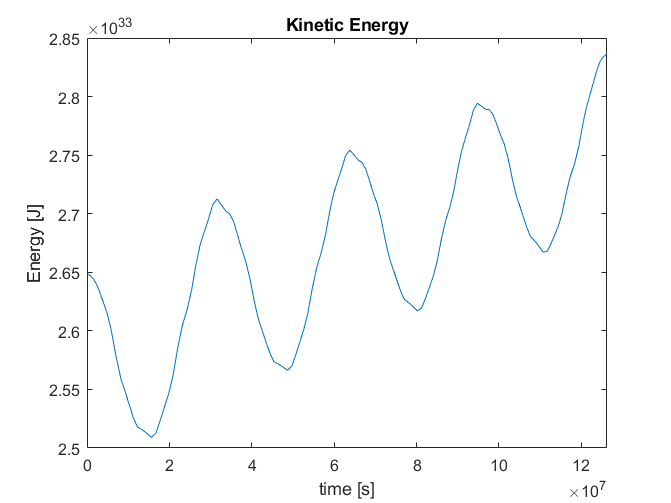

    
    figure(15);
    plot(U(:,1), 0.5*m.*(V(:,1).^2+V(:,2).^2))
    xlim([0, T]);    
  %  ylim([2.6e+33, 2.7e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Kinetic Energy');

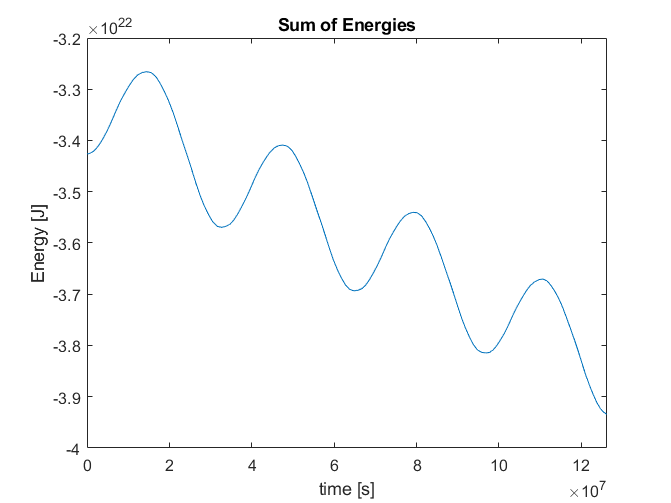

    
    figure(16);
    plot(U(:,1), -G*M*m./(V(:,3).^2+V(:,4).^2) +0.5.*(V(:,1).^2+V(:,2).^2))
    xlim([0, T]);    
%    ylim([2.6e+33, 2.7e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Sum of Energies');

Az **ode45** megoldható polárkoordinátás felírásban is.

Itt a két bázisvektor: $\hat{r}=\hat{x}cos(\theta)+\hat{y}sin(\theta)$, és $\hat{\theta}=-\hat{x}sin(\theta)+\hat{y}cos(\theta)$.

ebből levezethető, hogy $$\textbf{v}=\frac{d\textbf{r}}{dt}=\dot{r}\cdot\hat{r}+ r\cdot\dot{\theta}\cdot\hat{\theta}$$  és $ \textbf{a}=\frac{d\textbf{v}}{dt}=\hat{r}\cdot(\ddot{r}-r\dot{\theta}^2)+\hat{\theta}\cdot(2\dot{r}\dot{\theta}+r\ddot{\theta})$

Az erőtörvény: $$$F=-G \frac{mM}{r^2}\cdot \hat{r}$$$, ebből a mozgásegyenlet: $$$\textbf{a}=-G \frac{M}{r^2}\cdot \hat{r}$$.

Behelyettesítve: $ \textbf{a}=\hat{r}\cdot(\ddot{r}-r\dot{\theta}^2)+\hat{\theta}\cdot(2\dot{r}\dot{\theta}+r\ddot{\theta})=-G \frac{M}{r^2}\cdot \hat{r}$. Ebből $2\dot{r}\dot{\theta}+r\ddot{\theta}=\frac{1}{r}\frac{d}{dt}(r^2\dot{\theta})=0$, így legyen $r^2\dot{\theta}=h$   konstans, ami a perdület $(\dot{\theta}=\frac{h}{r^2})$. A perdület: $h=r_0\cdot \sqrt{v_{x0}+v_{y0}}$.

Így $\hat{r}\cdot(\ddot{r}-r\dot{\theta}^2)=-G \frac{M}{r^2}\cdot \hat{r}$, $\hat{r}$-val egyszerűsítve: 

$\ddot{r}=-G \frac{M}{r^2}+r\dot{\theta}^2=-G \frac{M}{r^2}+\frac{h^2}{r^3}$, ami a mozgásegyenlet.

A differenciálegyenletrendszer:

$r(1)=r$, $r(2)=\dot{r}$, $r(3)={\theta}$

A kinetikus és potenciális energia:

$E_{pot}=-G\frac{mM}{r}=-G\frac{mM}{r(1)}$, és $E_{kin}=\frac{1}{2}mv^2=\frac{1}{2}m(\dot{r}+ r\cdot\dot{\theta})^2=\frac{1}{2}m\big(r(2)+\frac{h}{r(1)}\big)$

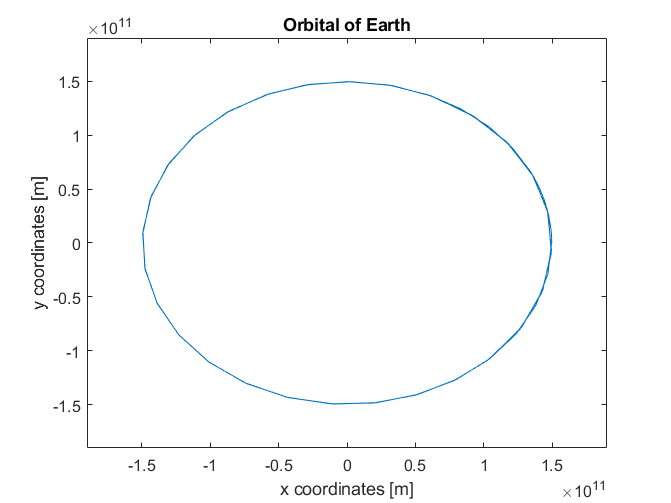

M=1.98847e+30;      %Nap tömege [kg]
m=5.9722e+24;       %Föld tömege [kg]
G=6.67404e-11;      %gravitációs állandó [m^3*kg^{-1}*s^{-2}]
r_nap=696342000;
R=149.6e+9;     %átlagos távolság a Naptól [m]

year=4;

T=365.256*24*60*60*year;     %keringési idő [s]

x=R;
y=0;
v0=29.78e+3;
vx=0;
vy=v0;
t=0; 
E_pot=-G*M*m / (x^2+y^2);
E_kin=(vx^2+vy^2)*m / 2;
E_sum=E_pot+E_kin;

h=R*(vx^2+vy^2)^(0.5);      %r^2*theta derivalt, perdulet egysegnyi tomegre

kezdeti_feltetelek=[x, 0, 0];               %r, kezdeti teta derivalt,  teta
diff=@(t,r) [r(2); -G*M/r(1)^2+h^2/r(1)^3; h/r(1)^2];
[U, V] = ode45(diff, [0 T], kezdeti_feltetelek);

figure(17);
plot(cos(V(:,3)).*V(:, 1), sin(V(:,3)).*V(:,1));
xlim([-190e+9, 190e+9]);
ylim([-190e+9, 190e+9]);
xlabel('x coordinates [m]');
ylabel('y coordinates [m]');
title('Orbital of Earth');

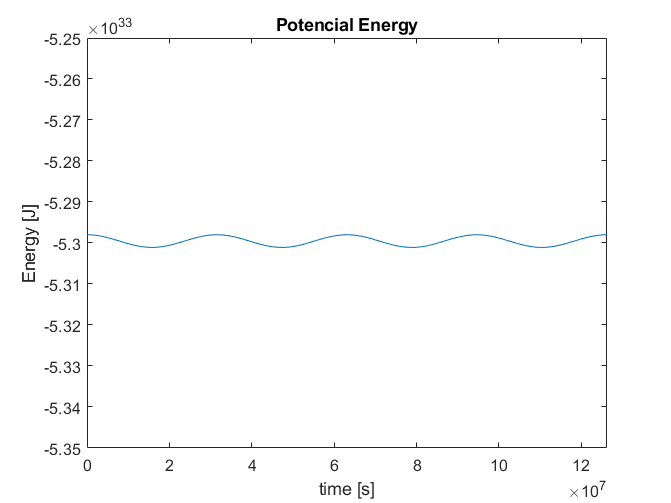


    figure(18);
    plot(U(:,1), -G*M*m./V(:,1))
    xlim([0, T]);
    ylim([-5.35e+33, -5.25e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Potencial Energy');

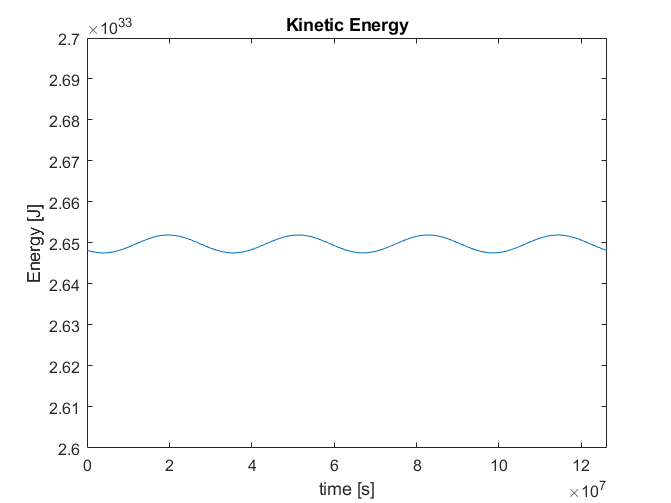

    
    figure(19);
    plot(U(:,1), 0.5*m.*(h./V(:,1)+V(:,2)).^2)
    xlim([0, T]);    
    ylim([2.6e+33, 2.7e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Kinetic Energy');

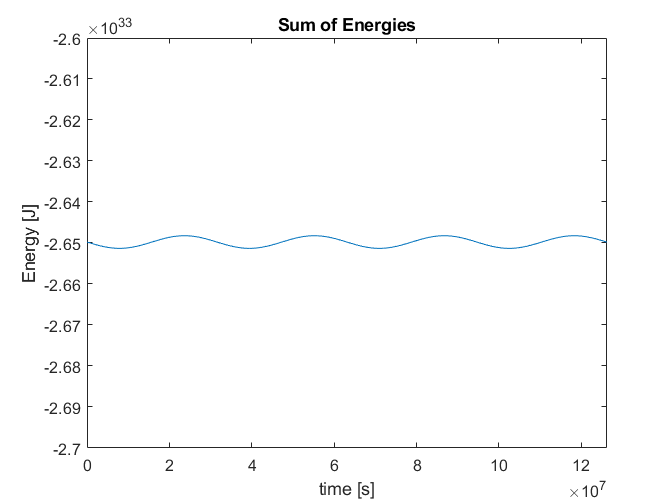

    
    figure(20);
    plot(U(:,1), -G*M*m./V(:,1) +0.5*m.*(h./V(:,1)+V(:,2)).^2)
    xlim([0, T]);    
    ylim([-2.7e+33, -2.6e+33]);
    xlabel('time [s]');
    ylabel('Energy [J]');
    title('Sum of Energies');

Készítette: Bánkövi Orsolya, DAZOJ8